# EXERCISE #1 :Simulate the Simplest Bluetooth LE Network

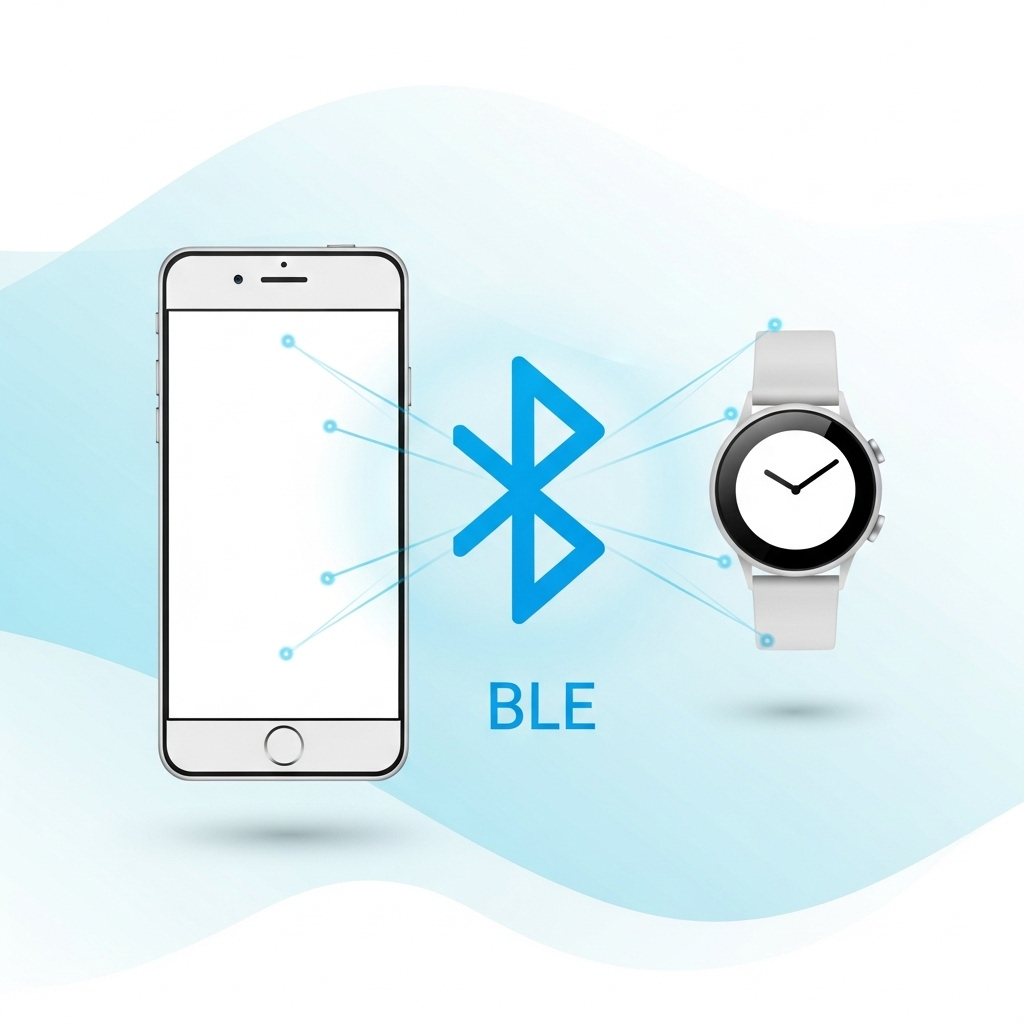

An example of two node Bluetooth LE network 

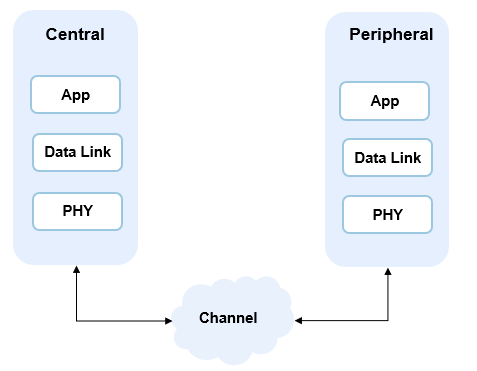

This exercise models all these blocks 

**In this exercise, you will:**

- Model a Bluetooth Low Energy (LE) network with one Central and one Peripheral node.

- Configure link-layer and physical-layer properties for the nodes.

- Add application traffic from the Central node to the Peripheral node.

- Integrate a custom channel into the wireless network simulator.

- Simulate the Bluetooth LE network, measure network KPIs, and retrieve statistics for both the Central and Peripheral nodes.

- Log and visualize Bluetooth LE packets and IQ samples.

p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows
wirelessnetworkSupportPackageCheck % Check if the required package for network simulation is installed 

#### Initilaize the wireless network simulator

networkSimulator = wirelessNetworkSimulator.init;
simulationTime = 0.5;

# Task #1/3 Create a Bluetooth LE Central Node

% Use bluetoothLENode() function to create a central node 
% Write configuration in a variable named "centralNode"
% Hint: Type "doc bluetoothLENode" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% "central", 
% "Name","Central"
% Position=[0 0 0]
% TransmitterPower=-20 in dBm
% TransmitterGain=0
% ReceiverGain=0
% ReceiverSensitivity=-100 in dBm

% Enter Code Here
% centralNode =  

#### **Create a Bluetooth LE node, specifying the role as **`"peripheral"`.

peripheralNode = bluetoothLENode("peripheral", ...
    Position=[0 1 0], ...
    Name="Peripheral", ...
    TransmitterPower=-20, ...
    TransmitterGain=0, ...
    ReceiverGain=0, ...
    ReceiverSensitivity=-100);

# Task #2/3  Configure the Connection Parameters between Central and Peripheral Nodes   

% Use bluetoothLEConnectionConfig() function to configure the connection 
% Write configuration in a variable named "cfgConnection"
% Hint: Type "doc bluetoothLEConnectionConfig" in the MATLAB Command Window, and see the "Syntax" section.
% PHY mode for generating or decoding, specified as "LE1M", "LE2M", "LE125K", or "LE500K".
% Note : use the following values to start with
% PHYMode = "LE1M" 
% ConnectionInterval=0.050
% AccessAddress="5DA44270"

% Enter Code Here
% cfgConnection =

#### Configure the connection between the central and peripheral 

configureConnection(cfgConnection,centralNode,peripheralNode);

# Task 3/3: Create the Custom Channel Configuration  

% Bluetooth uses several techniques that mitigate multipath fading: 
% 1. Frequency Hopping Spread Spectrum (FHSS)
% 2. Short Packets
% 3. Error Correction & Retransmissions
% Forward Error Correction (FEC) and Automatic Repeat Request (ARQ) reduce the effect of fading-induced errors.
% Use bluetoothPathLossConfig() function to define a function implementing a propagation channel model
% Signal propagation environment, specified as "Home", "Industrial", "Office", or "Outdoor".
% Hint: type doc bluetoothPathLossConfig and see the "Syntax" section.
% Note : use the following values as argument 
% Environment="Industrial"
% PathLossExponent=2.2

% Enter Code Here
% cfgPathloss = 

#### Add the channel to the network simulator 

addImpairment = @(rxInfo,txData) updatePathLoss(rxInfo,txData,cfgPathloss); % Path loss function
addChannelModel(networkSimulator,addImpairment);

#### Add bidirectional traffic 

enableDataTraffic = false;
dataRate = 30; 
if enableDataTraffic
    traffic = networkTrafficOnOff(DataRate=dataRate,PacketSize=251,GeneratePacket=true,OnTime=inf,OffTime=0);
    addTrafficSource(centralNode,traffic,"DestinationNode",peripheralNode);
    traffic = networkTrafficOnOff(DataRate=dataRate,PacketSize=251,GeneratePacket=true,OnTime=inf,OffTime=0);
    addTrafficSource(peripheralNode,traffic,"DestinationNode",centralNode);
    plotTrafficPattern(simulationTime,traffic)
end

#### Add the Central and Peripheral nodes to the wireless network simulator.

nodes = [centralNode peripheralNode];
addNodes(networkSimulator,nodes)

#### Visualize Packet Transitions

plotFrequencyFlag = false; 
helperPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=plotFrequencyFlag);

#### Enable Packet Capture 

clear packetCaptureObj;
packetCaptureObj = helperPacketCapture(nodes,"pcap");

#### Enable capture of IQ samples

enableIQVisualization  = false;
if enableIQVisualization
    iqSampleObj = helperCaptureIQSamples(peripheralNode);
end

#### Run the simulation

run(networkSimulator,simulationTime)

#### Retrieve application, link layer (LL), and physical layer (PHY) statistics. For more information, see [Bluetooth LE Node Statistics](https://www.mathworks.com/help/bluetooth/ug/bluetooth-le-node-statistics.html).

centralStats = statistics(centralNode);
peripheralStats = statistics(peripheralNode);
fprintf(['Central Node Transmission Time: %f seconds\n ' ...
         'Central Node Listen Time: %f seconds\n ' ...
         'Central Node Sleep Time: %f seconds\n ' ...
         'Central Node Idle Time: %f seconds'], ...
         centralStats.LL(1).TransmissionTime, ...
         centralStats.LL(1).ListenTime, ...
         centralStats.LL(1).SleepTime, ...
         centralStats.LL(1).IdleTime);

#### Measure application, link layer (LL), and App layer KPIs

For more information about the KPIs, see [KPIs](https://in.mathworks.com/help/bluetooth/ref/bluetoothlenode.kpi.html).

throughput = kpi(centralNode,peripheralNode,"throughput",Layer="LL");
latency = kpi(centralNode,peripheralNode,"latency",Layer="App");
packetLossRatio = kpi(centralNode,peripheralNode,"PLR",Layer="App");
fprintf(['Throughput: %f kbps\n ' ...
         'Latency: %f seconds\n ' ...
         'Packet Loss Ratio: %f \n '], ...
          throughput, ...
          latency, ...
          packetLossRatio);


#### IQ sample visualization

if enableIQVisualization
    minTime = 0.2500;
    maxTime = 0.2522;
    mask = isbetween(iqSampleObj.IQSamples.Time, minTime, maxTime, 'openright');
    signalAnalyzer(iqSampleObj.IQSamples.Data(mask),SampleRate=80e6);
end

#### Create a custom channel that models Bluetooth path loss for an industrial scenario

function rxData = updatePathLoss(rxInfo,txData,pathlossCfg)
% Apply path loss and update output signal
rxData = txData;
% Calculate the distance between transmitter and receiver in meters
distance = norm(rxData.TransmitterPosition - rxInfo.Position);
pathloss = bluetoothPathLoss(distance,pathlossCfg);
rxData.Power = rxData.Power-pathloss;                           % In dBm
scale = 10.^(-pathloss/20);
[numSamples,~] = size(rxData.Data);
rxData.Data(1:numSamples,:) = rxData.Data(1:numSamples,:)*scale;
end

delete(packetCaptureObj);
%path(p);

Copyright 2021-2023 The MathWorks, Inc.